# Design Cooling System

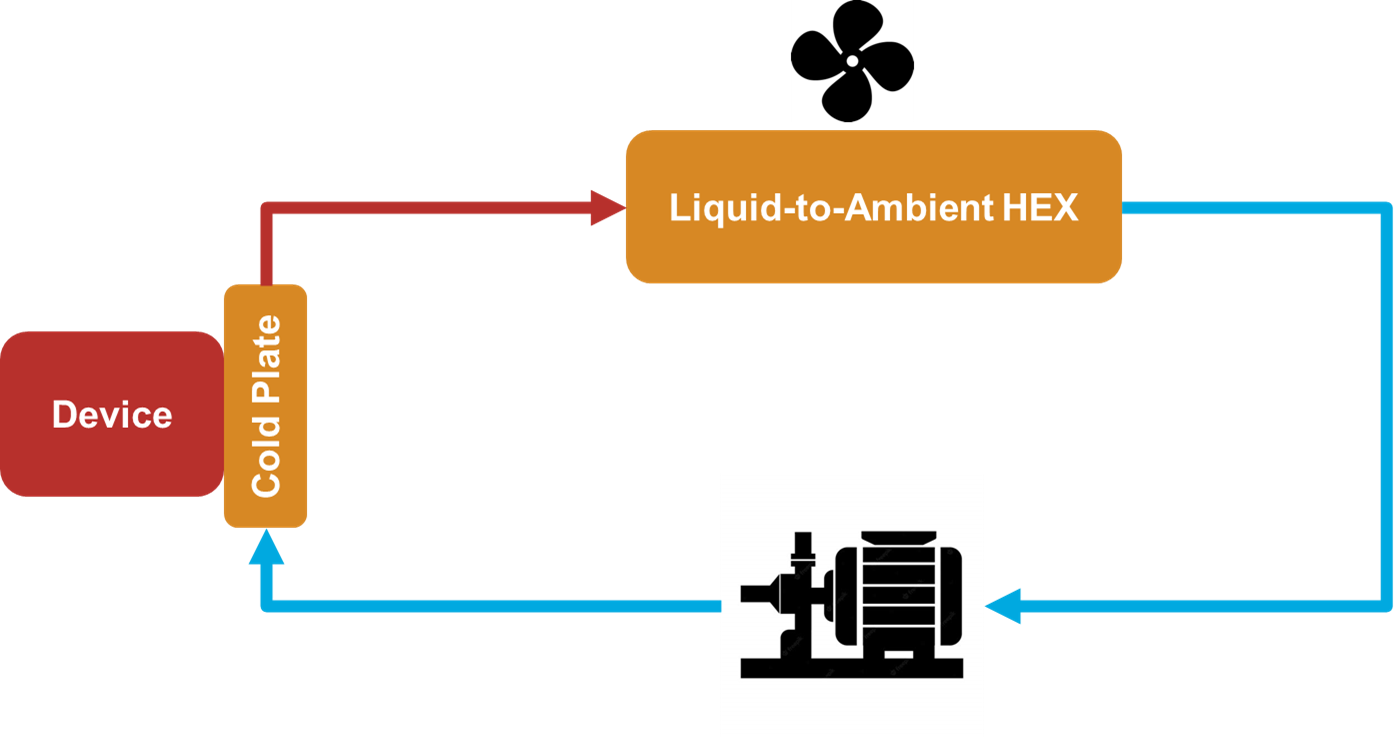

### Requirements for X-Ray Tube Cooling

- Remove up to 3 kW 

- Temperature set point: 20°C

- Nominal flow rate: 15 L/min

- Tout must ot excess 30°C 

- Temperature stability +/- n°C

- Working fluid: Water

- Operating conditions (at what temperatures is the thing operated and “where” is it) 15°C-40°C

- Device temperature should not exceed 50°C

Steady state calculations

Final surface temperature of cooled device


$$T_{\textrm{surface}} =Q_{\textrm{Diss}} *R_{\textrm{CP}} \;+T_{\textrm{cp},\textrm{in}}$$


Cold plate heat transfer


$$Q_{\textrm{Diss}} =\left(T_{\textrm{cp},\textrm{out}} -T_{\textrm{cp},\textrm{in}} \right)*{\dot{m} }_{\textrm{water}} *c_{p,\textrm{water}}$$


Heat transfer in ambient air heat exchanger


$$Q_{\textrm{Diss}} =\varepsilon *C_{\min } *\left(T_{\textrm{cp},\textrm{out}} -T_{\textrm{Air}} \right)$$


with 


$$C_{\textrm{water}} =\;$$

$${\dot{m} }_{\textrm{water}} *c_{p,\textrm{water}}$$



$$C_{\textrm{air}} =\;$$

$${\dot{m} }_{\textrm{air}} *c_{p,\textrm{air}}$$



$$C_{\min } =\min \left(C_{\textrm{water}} ,C_{\textrm{air}} \right)$$


#### Steady state cold plate outlet temperature for different flow rates at constant heat

flowRateVec  = 5:20;         % l/min
cp          = 4.18e3;       % J/(kg*K) heat cpacity of water at 20°C
rho         = 998.57;       % kg/m^3 density of water at 20°C
TcpIn      = 20;           % °C, water inlet temperature
QDiss       = 4e3;          % W, dissipated heat

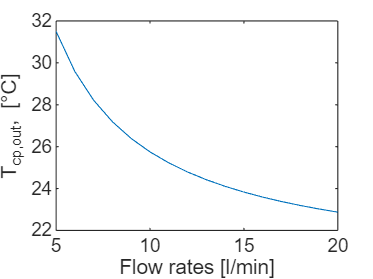

massFlowRates = flowRateVec*0.001/60*rho;
TcpOutVec = QDiss./(massFlowRates*cp)+TcpIn;

plot(flowRateVec,TcpOutVec)
xlabel('Flow rates [l/min]')
ylabel('T_{cp,out}, [°C]');
hold on

#### Verify in Simscape model 

for i = numel(flowRateVec):-1:1
    simInp(i) = Simulink.SimulationInput('example1');
    simInp(i) = simInp(i).setVariable('flowRate',flowRateVec(i));
end

simOut = sim(simInp)

[30-Apr-2025 17:12:39] Running simulations...


[30-Apr-2025 17:12:44] Completed 1 of 16 simulation runs


[30-Apr-2025 17:12:49] Completed 2 of 16 simulation runs


[30-Apr-2025 17:12:53] Completed 3 of 16 simulation runs


[30-Apr-2025 17:12:57] Completed 4 of 16 simulation runs


[30-Apr-2025 17:13:00] Completed 5 of 16 simulation runs


[30-Apr-2025 17:13:05] Completed 6 of 16 simulation runs


[30-Apr-2025 17:13:12] Completed 7 of 16 simulation runs
[30-Apr-2025 17:13:18] Completed 8 of 16 simulation runs
[30-Apr-2025 17:13:23] Completed 9 of 16 simulation runs
[30-Apr-2025 17:13:28] Completed 10 of 16 simulation runs
[30-Apr-2025 17:13:33] Completed 11 of 16 simulation runs
[30-Apr-2025 17:13:38] Completed 12 of 16 simulation runs
[30-Apr-2025 17:13:44] Completed 13 of 16 simulation runs
[30-Apr-2025 17:13:48] Completed 14 of 16 simulation runs
[30-Apr-2025 17:13:57] Completed 15 of 16 simulation runs
[30-Apr-2025 17:14:03] Completed 16 of 16 simulation runs


simOut = 1x16 Simulink.SimulationOutput array



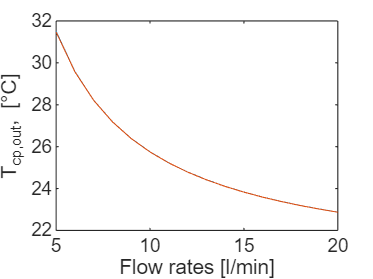

TcpOutVecSim = zeros(size(simInp));

for i = 1:numel(flowRateVec)
    TcpOutVec = simOut(i).simlog.Pipe_TL1.B.T.series.values('degC');
    TcpOutVecSim(i) = TcpOutVec(end);
end

plot(flowRateVec,TcpOutVecSim)
xlabel('Flow rates [l/min]')
ylabel('T_{cp,out}, [°C]');

#### Cold plate resistance 

#### Size cold plate

#### Size liquid-to-air heat exchanger